robot = Qbmove1D()

robot =   Qbmove1D with properties:

    actuator: [1×1 Qbmove]
        Dmax: 0.0848
        dimQ: 1
        dimX: 4
        dimU: 3
     inertia: 0.0300
          Df: 0.0020



x0 = [0; 0; 0; 0];
tension = 0.5;
qf = pi/3;
xf = [qf; 0; qf+tension; qf-tension ];
%xf = qf;
testtraj = TrajOptQbmove1D.reachFastIlqr(robot, x0, xf, 'tf', 1, 'dt', 0.02, 'tension', tension, 'sfactor', 1, 'ConstraintType', 1);

Iteration = 1; Cost = 503.2754; log(Lambda) = -0.2
Iteration = 2; Cost = 442.2348; log(Lambda) = -0.4
Iteration = 3; Cost = 442.2348; log(Lambda) = -0.2
Iteration = 4; Cost = 442.2348; log(Lambda) = 0.0
Iteration = 5; Cost = 366.0794; log(Lambda) = -0.2
Iteration = 6; Cost = 310.4482; log(Lambda) = -0.4
Iteration = 7; Cost = 252.7969; log(Lambda) = -0.6
Iteration = 8; Cost = 231.0925; log(Lambda) = -0.8
Iteration = 9; Cost = 224.6033; log(Lambda) = -1.0
Iteration = 10; Cost = 221.7275; log(Lambda) = -1.2
Iteration = 11; Cost = 218.8450; log(Lambda) = -1.4
Iteration = 12; Cost = 214.2891; log(Lambda) = -1.6
Iteration = 13; Cost = 212.9758; log(Lambda) = -1.8
Iteration = 14; Cost = 212.9758; log(Lambda) = -1.6
Iteration = 15; Cost = 212.9758; log(Lambda) = -1.4
Iteration = 16; Cost = 212.9758; log(Lambda) = -1.2
Iteration = 17; Cost = 212.9758; log(Lambda) = -1.0
Iteration = 18; Cost = 212.9758; log(Lambda) = -0.8
Iteration = 19; Cost = 212.9758; log(Lambda) = -0.6
Iteration = 20; Cost =

testtraj.SettlingTime

Reference to non-existent field 'SettlingTime'.

%stepinfo(testtraj.x(1,:), testtraj.t, 0.7, 'SettlingTimeShreshold', 0.02 )

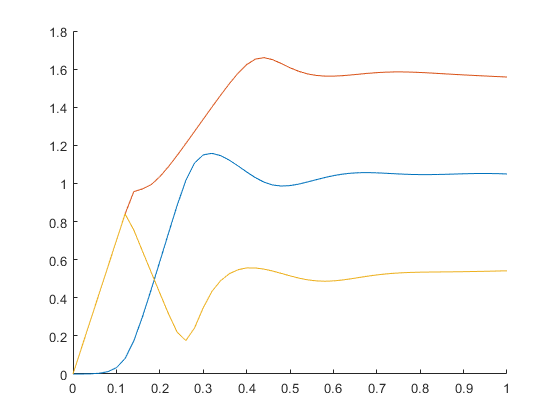

figure
hold on
plot(testtraj.t, testtraj.x(1,:))
plot(testtraj.t, testtraj.x(3,:))
plot(testtraj.t, testtraj.x(4,:))
hold off

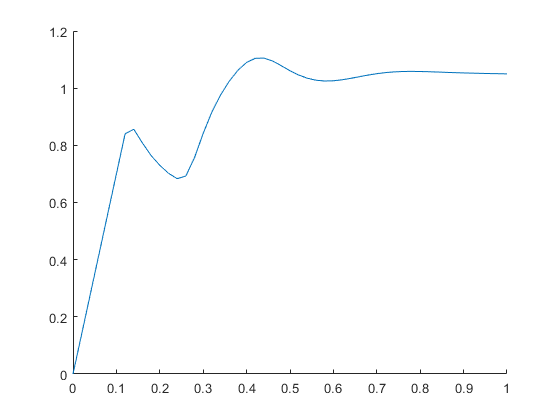


figure
hold on
plot(testtraj.t, (testtraj.x(3,:)+testtraj.x(4,:))/2)
hold off

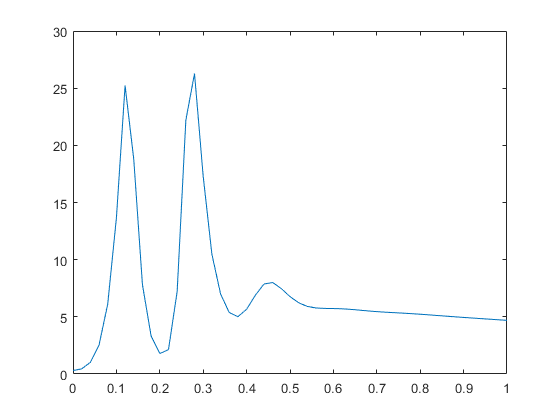


figure
plot(testtraj.t, robot.stiffness(testtraj.x))

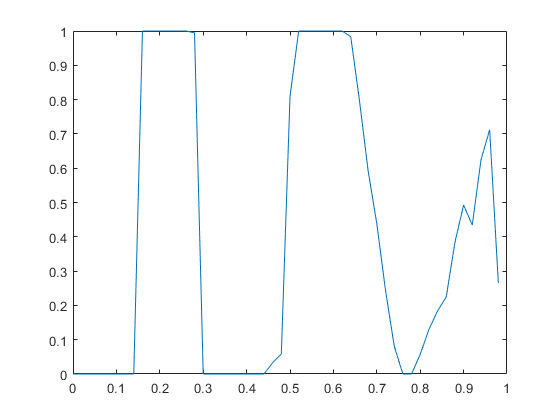


figure
plot(testtraj.t(1:end-1), testtraj.u(3,:))

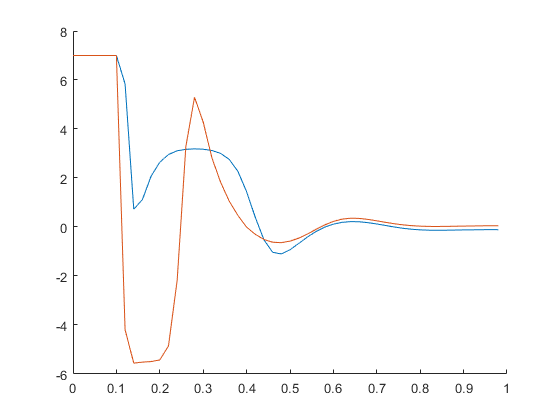

figure
hold on
xlim('auto')
ylim('auto')
plot(testtraj.t(1:end-1), testtraj.u(1,:))

xlim('auto')
ylim('auto')
plot(testtraj.t(1:end-1), testtraj.u(2,:))
hold off